# TEMPOmap Foreskin merge_spots

addpath('Z:/Documents/starmap_colab/Pipeline/');
addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:\Data\Processed\2022-10-15-Rena-SkinCulture254-gene\output\';

## Load TileConfiguration

current_well = '6'

current_well = '6'

rotation_degree = -270;

% merge dots 
stitch_file = fullfile(input_path,  '2022-10-29-rotation\rotated_dapi', strcat('Area_', current_well), "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y', 'z'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));
TileConfiguration.z = int32(fix(TileConfiguration.z));

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x       y     z 
    ____    ____    ___    __

    424        0      0     0
    415     1829     -4     0
    406     3662    -10    -1
    397     5492    -20     0
    388     7330    -23    -3



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));
offset_z = abs(min(TileConfiguration.z));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;
TileConfiguration.z = TileConfiguration.z + offset_z + 1;

## Merge dots

% load stitched dapi image
dapi_file = fullfile(input_path, "2022-10-30-stitching/dapi/", append('Area', current_well,'.tif'))

dapi_file = "Z:\Data\Processed\2022-10-15-Rena-SkinCulture254-gene\output\2022-10-30-stitching\dapi\Area6.tif"

% dapi_img = imread_big(dapi_file);
dapi_3d = imread_big(dapi_file);
dapi_max = max(dapi_3d, [], 3);

% create empty holders 
merged_points = int32([]);
merged_reads = {};
merged_region = [];

upd = textprogressbar(size(TileConfiguration,1), 'updatestep', 2);

Completed [                    ]   0% --:--:--

for r=1:size(TileConfiguration,1)
% for r=1:3
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile) 
    curr_dot_file = fullfile(input_path, "2022-10-24-spot-finding", curr_position_dir, "goodPoints_max3d.mat");
    if isfile(curr_dot_file)
        load(curr_dot_file); 
        
        %% a twist here: there are position folders that does not contain .mat file
        if ~isempty(tile_goodSpots)
             if rotation_degree == -90
                % rotate 90 c
                temp = tile_goodSpots;
                tile_goodSpots(:, 2) = temp(:, 1);
                tile_goodSpots(:, 1) = 2049 - temp(:, 2);
             elseif rotation_degree == -180
                % rotate 180 c
                temp = tile_goodSpots;
                tile_goodSpots(:, 1) = 2049 - temp(:, 1);
                tile_goodSpots(:, 2) = 2049 - temp(:, 2);
             elseif rotation_degree == -270
                % rotate 270 c
                temp = tile_goodSpots;
                tile_goodSpots(:, 1) = temp(:, 2);
                tile_goodSpots(:, 2) = 2049 - temp(:, 1);
             end
            
            tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);    
            % construct dots region
            current_min = min(tile_goodSpots, [], 1);
            current_max = max(tile_goodSpots, [], 1);
            if current_max(1) > size(dapi_max, 2)
                % fprintf("1")
                current_max(1) = size(dapi_max, 2);
                toKeep = tile_goodSpots(:, 1) <= current_max(1);
                tile_goodSpots = tile_goodSpots(toKeep, :);
                tile_goodReads = tile_goodReads(toKeep);
            
            else if current_max(2) > size(dapi_max, 1)
                    % fprintf("2")
                    current_max(2) = size(dapi_max, 1);   
                    toKeep = tile_goodSpots(:, 2) <= current_max(2);
                    tile_goodSpots = tile_goodSpots(toKeep, :);
                    tile_goodReads = tile_goodReads(toKeep);
                  
            end
            end
            current_region = zeros(size(dapi_max));
            current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
            % current_region(y+1:current_max(2), x+1:current_max(1)) = 1;
            
            % merge dots 
            if isempty(merged_region)
                merged_region = current_region;
            else
                current_overlap = merged_region & current_region;
                merged_region = merged_region | current_region;
                current_region = current_region - current_overlap; 
                
                temp_cell = num2cell(tile_goodSpots, 2); 
                current_lindex = cellfun(@(x) sub2ind([size(dapi_3d)], x(2), x(1)), temp_cell);
                current_logical = logical(current_region(current_lindex));
                tile_goodSpots = tile_goodSpots(current_logical, :);
                tile_goodReads = tile_goodReads(current_logical);
            end
            
            % save current 
            merged_points = [merged_points; tile_goodSpots]
            merged_reads = [merged_reads; tile_goodReads];
        end
    end
    upd(r);
end

curr_position_dir = "Position424"

merged_points = 32476×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position415"

merged_points = 64501×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [                    ]   2% 00:01:04

curr_position_dir = "Position406"

merged_points = 105531×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position397"

merged_points = 144602×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=                   ]   5% 00:01:12

curr_position_dir = "Position388"

merged_points = 182981×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position379"

merged_points = 231521×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=                   ]   8% 00:01:14

curr_position_dir = "Position370"

merged_points = 274323×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position361"

merged_points = 274325×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==                  ]  11% 00:01:11

curr_position_dir = "Position425"

merged_points = 300891×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position416"

merged_points = 324841×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==                  ]  13% 00:01:08

curr_position_dir = "Position407"

merged_points = 346980×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position398"

merged_points = 374774×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===                 ]  16% 00:01:06

curr_position_dir = "Position389"

merged_points = 417857×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position380"

merged_points = 468081×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===                 ]  19% 00:01:06

curr_position_dir = "Position371"

merged_points = 499861×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position362"

merged_points = 540005×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [====                ]  22% 00:01:04

curr_position_dir = "Position426"

merged_points = 584765×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position417"

merged_points = 612177×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=====               ]  25% 00:01:03

curr_position_dir = "Position408"

merged_points = 643560×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position399"

merged_points = 665898×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=====               ]  27% 00:00:60

curr_position_dir = "Position390"

merged_points = 697940×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position381"

merged_points = 737862×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [======              ]  30% 00:00:58

curr_position_dir = "Position372"

merged_points = 766558×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position363"

merged_points = 811996×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [======              ]  33% 00:00:56

curr_position_dir = "Position427"

merged_points = 851422×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position418"

merged_points = 880802×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=======             ]  36% 00:00:54

curr_position_dir = "Position409"

merged_points = 905691×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position400"

merged_points = 936137×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=======             ]  38% 00:00:51

curr_position_dir = "Position391"

merged_points = 969333×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position382"

merged_points = 992373×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [========            ]  41% 00:00:49

curr_position_dir = "Position373"

merged_points = 1025987×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position364"

merged_points = 1059811×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [========            ]  44% 00:00:47

curr_position_dir = "Position428"

merged_points = 1100046×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position419"

merged_points = 1129931×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=========           ]  47% 00:00:45

curr_position_dir = "Position410"

merged_points = 1155036×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position401"

merged_points = 1184768×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==========          ]  50% 00:00:42

curr_position_dir = "Position392"

merged_points = 1219023×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position383"

merged_points = 1251187×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==========          ]  52% 00:00:40

curr_position_dir = "Position374"

merged_points = 1294329×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position365"

merged_points = 1321507×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===========         ]  55% 00:00:38

curr_position_dir = "Position429"

merged_points = 1361936×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position420"

merged_points = 1391100×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===========         ]  58% 00:00:36

curr_position_dir = "Position411"

merged_points = 1425013×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position402"

merged_points = 1474062×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [============        ]  61% 00:00:33

curr_position_dir = "Position393"

merged_points = 1510332×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position384"

merged_points = 1549426×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [============        ]  63% 00:00:31

curr_position_dir = "Position375"

merged_points = 1587909×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position366"

merged_points = 1626774×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=============       ]  66% 00:00:29

curr_position_dir = "Position430"

merged_points = 1648047×3 int32 matrix
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position421"

merged_points = 1672063×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=============       ]  69% 00:00:26

curr_position_dir = "Position412"

merged_points = 1696812×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position403"

merged_points = 1725690×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==============      ]  72% 00:00:24

curr_position_dir = "Position394"

merged_points = 1755472×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position385"

merged_points = 1790963×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===============     ]  75% 00:00:21

curr_position_dir = "Position376"

merged_points = 1830756×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position367"

merged_points = 1860050×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [===============     ]  77% 00:00:19

curr_position_dir = "Position431"

merged_points = 1881115×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position422"

merged_points = 1894936×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [================    ]  80% 00:00:16

curr_position_dir = "Position413"

merged_points = 1917328×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position404"

merged_points = 1938572×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [================    ]  83% 00:00:14

curr_position_dir = "Position395"

merged_points = 1966008×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position386"

merged_points = 1995151×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=================   ]  86% 00:00:12

curr_position_dir = "Position377"

merged_points = 2026176×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position368"

merged_points = 2051182×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=================   ]  88% 00:00:09

curr_position_dir = "Position432"

merged_points = 2095067×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position423"

merged_points = 2122924×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==================  ]  91% 00:00:07

curr_position_dir = "Position414"

merged_points = 2147773×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position405"

merged_points = 2178944×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [==================  ]  94% 00:00:05

curr_position_dir = "Position396"

merged_points = 2210083×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position387"

merged_points = 2247700×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [=================== ]  97% 00:00:02

curr_position_dir = "Position378"

merged_points = 2274449×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


curr_position_dir = "Position369"

merged_points = 2299965×3
    907   1825     12
    914   1821     12
    906   1820     12
    447   1787     12
    603   1761     13
    821   1724     12
    913   1668     12
    956   1536     12
    912   1498     12
    976   1481     12


Completed [====================] Done. [84 seconds]


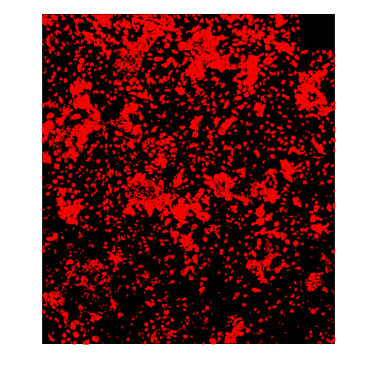


merged_points(:,1) = merged_points(:,1) - 1;
merged_points(:,2) = merged_points(:,2) - 1;
merged_points(:,3) = merged_points(:,3) - 1;

z = 20;
plot_centroids(merged_points(merged_points(:, 3) == z, :), dapi_3d(:,:,z), 1)

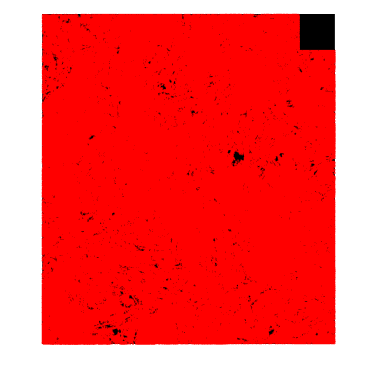


plot_centroids(merged_points, dapi_max, 1)

## output

spot_out_path = fullfile(input_path, '2022-11-07-merged-points', append('Area', current_well));
if ~exist(spot_out_path, 'dir')
    mkdir(spot_out_path)
end
save(fullfile(input_path, '2022-11-07-merged-points', append('Area', current_well), 'merged_goodPoints.mat'), "merged_points", "merged_reads");